clear;
close all;
clc;
initime = clock;
addpath('../funcs/');
load ../../data/all_0_0.5_0_0.05_Iattn_0.02.mat;
% svfolder= "../../paper/figure2/"; for journal paper
svfolder = "../../../../DThesis/chapter2/";

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 4;
steps = size(orderSheet,1);

## Parameter Plane

level = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,1) < levelSheet(i,j,2) && levelSheet(i,j,1) < levelSheet(i,j,5)
            level(i,j) = 1;
        end
    end
end

figure();

% INF
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if orderSheet(i,j) == -1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor",[209 211 212]/256); % grey
    hold on
end

% ROI: OSC-OSC: order and level agree
roi = zeros(steps,steps);
% dont consider S1 and S1S2+A1
for i = 1:steps
    for j = 1:steps
        if level(i,j) == 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end

% % consider S1>S1S2+A1
% for i = 1:steps
%     for j = 1:steps
%         if level(i,j) == 1 && orderSheet(i,j) == 1 && levelSheet(i,j,6) > levelSheet(i,j,3)
%             roi(i,j) = 1;
%         end
%     end
% end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#EA4335"); % red
    hold on
end

% OSC-OSC: order disagree
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if orderSheet(i,j) ~= 1 && sum(osciSheet(i,j,1,:)==1)==5 && sum(osciSheet(i,j,2,:)==1)==5
            roi(i,j) = 1;
        end
    end
end

for i = 1:steps
    for j = 1:steps
        if level(i,j) ~= 1 && orderSheet(i,j) == 1
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#34A853"); % green
    hold on
end

% STY-STY
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if orderSheet(i,j) ~= -1 && sum(osciSheet(i,j,2,:)==1)<5
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#4285F4"); % blue
    hold on
end


% gamma/+beta but order agree
roi = zeros(steps,steps);
% dont consider S1 and S1S2+A1
for i = 1:steps
    for j = 1:steps
        if level(i,j) == 1 && orderSheet(i,j) == 1 && sum(betaSheet(i,j,:)>0)>0
            roi(i,j) = 1;
        end
    end
end

% consider S1>S1S2+A1
% for i = 1:steps
%     for j = 1:steps
%         if level(i,j) == 1 && orderSheet(i,j) == 1 && sum(betaSheet(i,j,:)>0)>0 && levelSheet(i,j,2) > levelSheet(i,j,5)
%             roi(i,j) = 1;
%         end
%     end
% end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FBBC05"); % yellow
    hold on
end

% for journal paper
textSize = 8;
text(0.05, 0.04, 'B', 'FontSize',textSize)
text(0.11, 0.04,'C', 'FontSize',textSize);
text(0.15, 0.04,'D', 'FontSize',textSize);
text(0.2, 0.04,'E', 'FontSize',textSize);
text(0.35, 0.04,'F', 'FontSize',textSize);
text(0.2, 0.02,'G', 'FontSize',textSize);
text(0.2, 0.0095,'H', 'FontSize',textSize);

% % for thesis
% size = 30;
% scatter(0.05, 0.04, size, '*', "k")
% scatter(0.11, 0.04, 200, '.', "k");
% scatter(0.15, 0.04, size, 'diamond', 'filled',"MarkerFaceColor","k");
% scatter(0.2, 0.04, size, 'v', 'filled',"MarkerFaceColor","k");
% scatter(0.35, 0.04, size, '<', 'filled',"MarkerFaceColor","k");
% scatter(0.2, 0.02, 50, 'pentagram', 'filled',"MarkerFaceColor","k");
% scatter(0.2, 0.0095, size, '>', 'filled',"MarkerFaceColor","k");

xlabel("\Delta_{back}^{E}");
ylabel("\Delta_{back}^{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
box on;

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
% for journal
% print(svfolder+'paraPlane', '-dpng', '-r600');
% print(svfolder+'paraPlane', '-dsvg', '-r600');
% for thesis
print(svfolder+'markedparaplane', '-dpng', '-r600');
print(svfolder+'markedparaplane', '-dsvg', '-r600');

## make legends

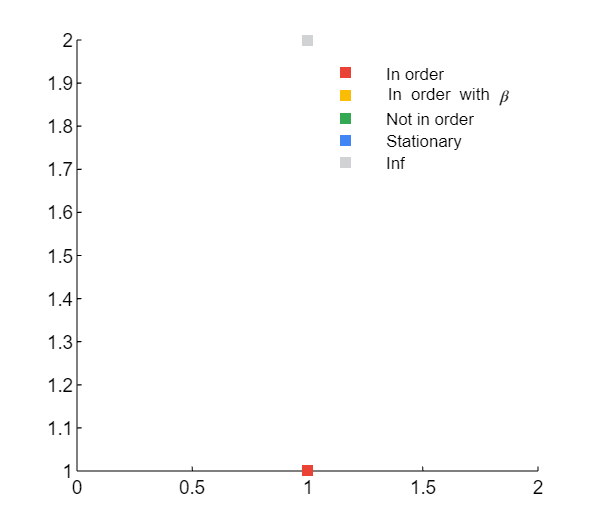

figure()
s1 = scatter(1,1,'s','filled',"MarkerFaceColor","#EA4335"); % red
hold on
s2 = scatter(1,2,'s','filled',"MarkerFaceColor","#FBBC05"); % yellow
s3 = scatter(1,2,'s','filled',"MarkerFaceColor","#34A853"); % green
s4 = scatter(1,2,'s','filled',"MarkerFaceColor","#4285F4"); % blue
s5 = scatter(1,2,'s','filled',"MarkerFaceColor",[209 211 212]/256); % grey
whitebg([1 1 1]);

lgd = legend([s1 s2 s3 s4 s5],["In order", "In order with \beta","Not in order", "Stationary","Inf"]);
legend boxoff  
lgd.FontName = 'Arial';
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
x0 = 0; y0 = 0; width = 9; height = 8;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
print(svfolder+'planeLegend', '-dpng', '-r600');
print(svfolder+'planeLegend', '-dsvg', '-r600');
print(svfolder+'planeLegend', '-dpdf', '-r600');

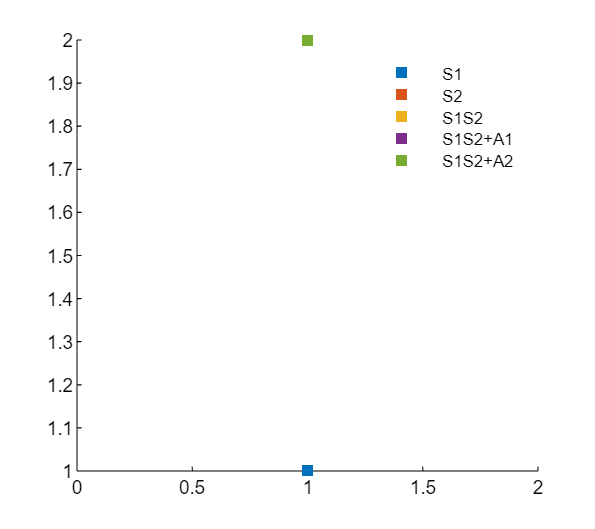


figure()
s1 = scatter(1,1,'s','filled',"MarkerFaceColor","#0072BD");
hold on
s2 = scatter(1,2,'s','filled',"MarkerFaceColor","#D95319");
s3 = scatter(1,2,'s','filled',"MarkerFaceColor","#EDB120"); 
s4 = scatter(1,2,'s','filled',"MarkerFaceColor","#7E2F8E"); 
s5 = scatter(1,2,'s','filled',"MarkerFaceColor","#77AC30"); 
whitebg([1 1 1]);

lgd = legend([s1 s2 s3 s4 s5],["S1", "S2","S1S2", "S1S2+A1","S1S2+A2"]);
legend boxoff  
lgd.FontName = 'Arial';
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
x0 = 0; y0 = 0; width = 9; height = 8;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
print(svfolder+'timecourseLegend', '-dpng', '-r600');
print(svfolder+'timecourseLegend', '-dsvg', '-r600');
print(svfolder+'timecourseLegend', '-dpdf', '-r600');

## B: stationary

Delta_e = 0.05;
Delta_i = 0.04; % none % changable
Iattn = 0.02;

time = 9000;
stimIn = 5000;
[r,~,~] = once(Delta_e, Delta_i, Iattn, time, stimIn);

r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

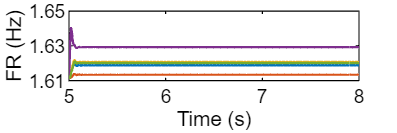

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [1.56 1.56 1.66 1.66];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond1,'Color','#0072BD','LineWidth',1);
hold on;
plot(timeax,r_cond2,'Color','#D95319','LineWidth',1);
plot(timeax,r_cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',1);

axis([stimIn/1000 (time-1000)/1000 1.61 1.65]);
xlabel("Time (s)");
ylabel("FR (Hz)");
yticks([1.61 1.63 1.65]);
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawB', '-dpng', '-r600');
print(svfolder+'rawB', '-dsvg', '-r600');

## C:Not in order raw

Delta_e = 0.11;
Delta_i = 0.04; % none % changable
Iattn = 0.02;

time = 9000;
stimIn = 5000;
[r,~,~] = once(Delta_e, Delta_i, Iattn, time, stimIn);

r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';


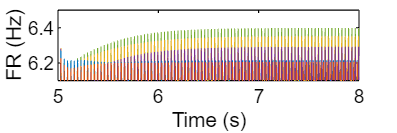

figure();
hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [6 6 7 7];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.3);
plot(timeax,r_cond3,'Color','#EDB120','LineWidth',0.3);
plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,r_cond1,'Color','#0072BD','LineWidth',0.3);
plot(timeax,r_cond2,'Color','#D95319','LineWidth',0.3);

axis([stimIn/1000 (time-1000)/1000 6.1 6.5]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawC', '-dpng', '-r600');
print(svfolder+'rawC', '-dsvg', '-r600');

## C:Not in order env

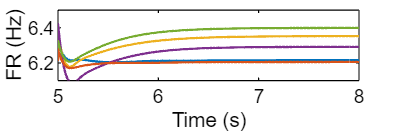

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [6 6 7 7];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

axis([stimIn/1000 (time-1000)/1000 6.1 6.5]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'envC', '-dpng', '-r600');
print(svfolder+'envC', '-dsvg', '-r600');

## C: PSD

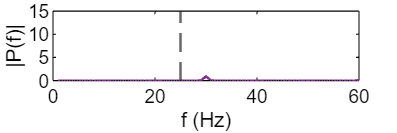

maxFreq = 60;
[f,P1] = getPSD(squeeze(r(5,end-100000:end,:)),maxFreq);
figure();
plot(f,P1(:,4),'Color','#7E2F8E','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
axis([0 maxFreq 0 15]);
xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdC', '-dpng', '-r600');
print(svfolder+'psdC', '-dsvg', '-r600'); % not eps due to font

## D:Not in order raw

Delta_e = 0.15;
Delta_i = 0.04; % none % changable
Iattn = 0.02;

time = 40000;
stimIn = 5000;
[r,~,~] = once(Delta_e, Delta_i, Iattn, time, stimIn);
r = r*1000;

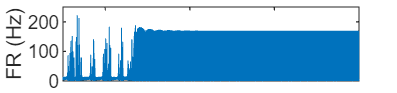

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 250 250];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

p1 = plot(timeax,r_cond1,'Color','#0072BD','LineWidth',0.1);

axis([stimIn/1000 time/1000 0 250]);
ylabel("FR (Hz)");
set(gca,'XTickLabels',[]);

box on;
x0 = 0; y0 = 0; width = 6; height = 1.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawD1', '-dpng', '-r600');
print(svfolder+'rawD1', '-dsvg', '-r600');

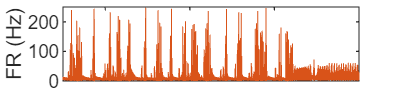


figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 250 250];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

p2 = plot(timeax,r_cond2,'Color','#D95319','LineWidth',0.1);

axis([stimIn/1000 time/1000 0 250]);
ylabel("FR (Hz)");
set(gca,'XTickLabels',[]);

box on;
x0 = 0; y0 = 0; width = 6; height = 1.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawD2', '-dpng', '-r600');
print(svfolder+'rawD2', '-dsvg', '-r600');

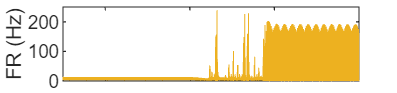


figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 250 250];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

p3 = plot(timeax,r_cond3,'Color','#EDB120','LineWidth',0.1);

axis([stimIn/1000 time/1000 0 250]);
ylabel("FR (Hz)");
set(gca,'XTickLabels',[]);

box on;
x0 = 0; y0 = 0; width = 6; height = 1.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawD3', '-dpng', '-r600');
print(svfolder+'rawD3', '-dsvg', '-r600');

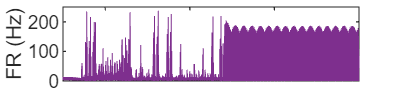


figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 250 250];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

p4 = plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.1);

axis([stimIn/1000 time/1000 0 250]);
ylabel("FR (Hz)");
set(gca,'XTickLabels',[]);

box on;
x0 = 0; y0 = 0; width = 6; height = 1.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawD4', '-dpng', '-r600');
print(svfolder+'rawD4', '-dsvg', '-r600');

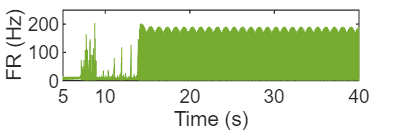


figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 250 250];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

p5 = plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.1);
xticks([5 10 20 30 40]);
axis([stimIn/1000 time/1000 0 250]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawD5', '-dpng', '-r600');
print(svfolder+'rawD5', '-dsvg', '-r600');

## D:Not in order env

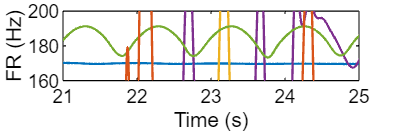

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

figure();

hold on;
% 
% recX = [1 time/1000 time/1000 1];
% recY = [6 6 7 7];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 5000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);


xlim([21 25]);
ylim([160 200]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'envD', '-dpng', '-r600');
print(svfolder+'envD', '-dsvg', '-r600');

## D: PSDs

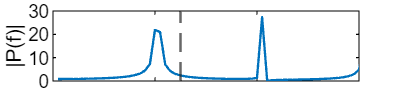

maxFreq = 60;

[f,P1] = getPSD(squeeze(r(5,end-100000:end,:)),maxFreq);
figure();
plot(f,P1(:,1),'Color','#0072BD','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
xlim([0 maxFreq]);
ylim([0 30]);
% xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
set(gca,'XTickLabels',[]);
x0 = 0; y0 = 0; width = 6; height = 1.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdD1', '-dpng', '-r600');
print(svfolder+'psdD1', '-dsvg', '-r600'); % not eps due to font

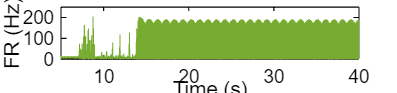


figure();
plot(f,P1(:,2),'Color','#D95319','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
xlim([0 maxFreq]);
ylim([0 30]);
% xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
set(gca,'XTickLabels',[]);
x0 = 0; y0 = 0; width = 6; height = 1.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdD2', '-dpng', '-r600');
print(svfolder+'psdD2', '-dsvg', '-r600'); % not eps due to font

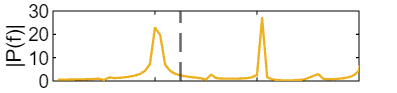


figure();
plot(f,P1(:,3),'Color','#EDB120','LineWidth',1);
hold on;
set(gca,'XTickLabels',[]);
xline(25,'--','LineWidth',1);
xlim([0 maxFreq]);
ylim([0 30]);
% xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 1.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdD3', '-dpng', '-r600');
print(svfolder+'psdD3', '-dsvg', '-r600'); % not eps due to font

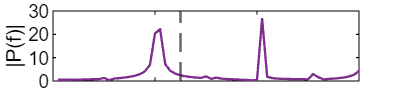


figure();
plot(f,P1(:,4),'Color','#7E2F8E','LineWidth',1);
hold on;
set(gca,'XTickLabels',[]);
xline(25,'--','LineWidth',1);
xlim([0 maxFreq]);
ylim([0 30]);
% xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 1.4;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdD4', '-dpng', '-r600');
print(svfolder+'psdD4', '-dsvg', '-r600'); % not eps due to font

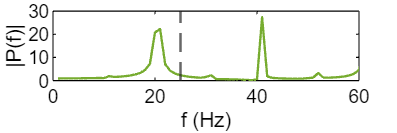


figure();
plot(f,P1(:,5),'Color','#77AC30','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
xlim([0 maxFreq]);
ylim([0 30]);
xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdD5', '-dpng', '-r600');
print(svfolder+'psdD5', '-dsvg', '-r600'); % not eps due to font

## E: not in order raw

Delta_e = 0.2;
Delta_i = 0.04; % none % changable
Iattn = 0.02;

time = 9000;
stimIn = 5000;
[r,~,~] = once(Delta_e, Delta_i, Iattn, time, stimIn);

r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

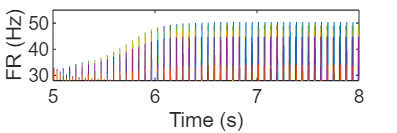

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 60 60];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond1,'Color','#0072BD','LineWidth',0.3);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.3);
plot(timeax,r_cond3,'Color','#EDB120','LineWidth',0.3);
plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,r_cond2,'Color','#D95319','LineWidth',0.3);

xlim([stimIn/1000 (time-1000)/1000]);
ylim([28 55]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawE', '-dpng', '-r600');
print(svfolder+'rawE', '-dsvg', '-r600');

## E:Not in order env

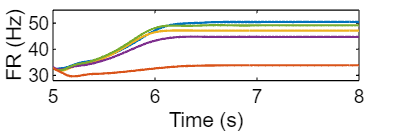

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 60 60];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

xlim([stimIn/1000 (time-1000)/1000]);
ylim([28 55]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'envE', '-dpng', '-r600');
print(svfolder+'envE', '-dsvg', '-r600');

## E: PSD

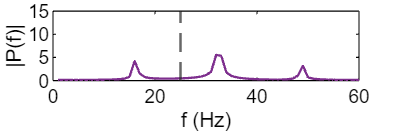

maxFreq = 60;
[f,P1] = getPSD(squeeze(r(5,end-100000:end,:)),maxFreq);
figure();
plot(f,P1(:,4),'Color','#7E2F8E','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
axis([0 maxFreq 0 15]);
xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdE', '-dpng', '-r600');
print(svfolder+'psdE', '-dsvg', '-r600'); % not eps due to font

## F: in order raw

Delta_e = 0.35;
Delta_i = 0.04; % none % changable
Iattn = 0.02;

time = 9000;
stimIn = 5000;
[r,~,~] = once(Delta_e, Delta_i, Iattn, time, stimIn);

r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

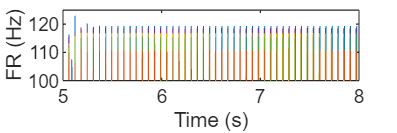

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 150 150];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond1,'Color','#0072BD','LineWidth',0.3);
plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,r_cond3,'Color','#EDB120','LineWidth',0.3);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.3);
plot(timeax,r_cond2,'Color','#D95319','LineWidth',0.3);

axis([stimIn/1000 (time-1000)/1000 100 125]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawF', '-dpng', '-r600');
print(svfolder+'rawF', '-dsvg', '-r600');

## F:in order env

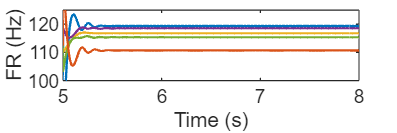

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [70 70 130 130];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

axis([stimIn/1000 (time-1000)/1000 100 125]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'envF', '-dpng', '-r600');
print(svfolder+'envF', '-dsvg', '-r600');

## F: PSD

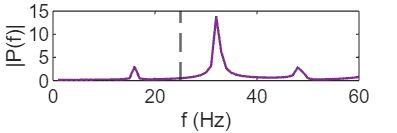

maxFreq = 60;
[f,P1] = getPSD(squeeze(r(5,end-100000:end,:)),maxFreq);
figure();
plot(f,P1(:,4),'Color','#7E2F8E','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
axis([0 maxFreq 0 15]);
xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdF', '-dpng', '-r600');
print(svfolder+'psdF', '-dsvg', '-r600'); % not eps due to font

## G: in order raw

Delta_e = 0.2;
Delta_i = 0.02; % none % changable
Iattn = 0.02;

time = 9000;
stimIn = 5000;
[r,~,~] = once(Delta_e, Delta_i, Iattn, time, stimIn);


r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

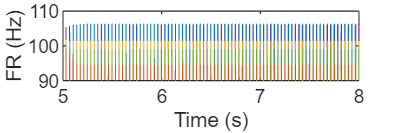

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 150 150];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,r_cond1,'Color','#0072BD','LineWidth',0.3);
plot(timeax,r_cond3,'Color','#EDB120','LineWidth',0.3);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.3);
plot(timeax,r_cond2,'Color','#D95319','LineWidth',0.3);

xlim([stimIn/1000 (time-1000)/1000]);
ylim([90 110]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawG', '-dpng', '-r600');
print(svfolder+'rawG', '-dsvg', '-r600');

## G:in order env

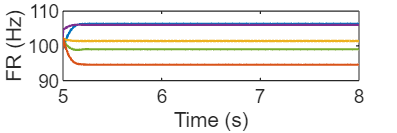

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [70 70 130 130];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

xlim([stimIn/1000 (time-1000)/1000])
ylim([90 110]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'envG', '-dpng', '-r600');
print(svfolder+'envG', '-dsvg', '-r600');

## G: PSD

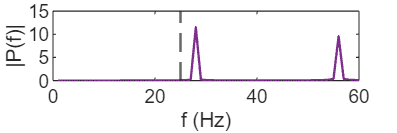

maxFreq = 60;
[f,P1] = getPSD(squeeze(r(5,end-100000:end,:)),maxFreq);
figure();
plot(f,P1(:,4),'Color','#7E2F8E','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
axis([0 maxFreq 0 15]);
xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdG', '-dpng', '-r600');
print(svfolder+'psdG', '-dsvg', '-r600'); % not eps due to font

## H: in order raw

Delta_e = 0.2;
Delta_i = 0.0095; % none % changable
Iattn = 0.02;

time = 9000;
stimIn = 5000;
[r,~,~] = once(Delta_e, Delta_i, Iattn, time, stimIn);

r = r*1000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

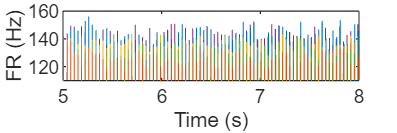

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,r_cond1,'Color','#0072BD','LineWidth',0.3);
plot(timeax,r_cond3,'Color','#EDB120','LineWidth',0.3);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',0.3);
plot(timeax,r_cond2,'Color','#D95319','LineWidth',0.3);

xlim([stimIn/1000 (time-1000)/1000])
ylim([110 160]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'rawH', '-dpng', '-r600');
print(svfolder+'rawH', '-dsvg', '-r600');

## H:in order env

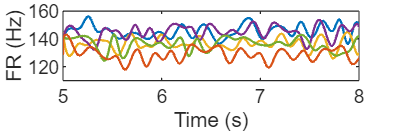

figure();

hold on;

% recX = [1 time/1000 time/1000 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',1);

xlim([stimIn/1000 (time-1000)/1000])
ylim([110 160]);
xlabel("Time (s)");
ylabel("FR (Hz)");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'envH', '-dpng', '-r600');
print(svfolder+'envH', '-dsvg', '-r600');

## H: PSD

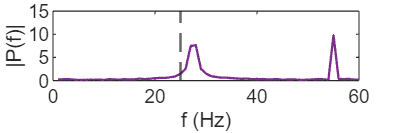

maxFreq = 60;
[f,P1] = getPSD(squeeze(r(5,end-100000:end,:)),maxFreq);
figure();
plot(f,P1(:,4),'Color','#7E2F8E','LineWidth',1);
hold on;
xline(25,'--','LineWidth',1);
axis([0 maxFreq 0 15]);
xlabel("f (Hz)");
ylabel("|P(f)|");
box on;
x0 = 0; y0 = 0; width = 6; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
print(svfolder+'psdH', '-dpng', '-r600');
print(svfolder+'psdH', '-dsvg', '-r600'); % not eps due to font